clearvars
% korelacja pozycja a skuteczność
dane=readtable('player_mvp_stats.csv');

dane=rmmissing(dane);
dane_pozycja=table2array(dane(:,2));
dane_skutecznosc=table2array(dane(:,10));
tabela=table(dane_pozycja, dane_skutecznosc)

tabela = 11817×2 table
    dane_pozycja    dane_skutecznosc
    ____________    ________________

       {'PF'}            0.476      
       {'SG'}            0.477      
       {'SF'}            0.492      
       {'PG'}            0.432      
       {'PG'}            0.477      
       {'C' }            0.496      
       {'PF'}            0.495      
       {'SG'}            0.443      
       {'SG'}            0.441      
       {'C' }            0.565      
       {'PF'}            0.476      
       {'SG'}            0.458      
       {'SF'}            0.469      
       {'PF'}            0.407      
       {'PG'}            0.222      
       {'C' }            0.448      


**H0: Cechy statystyczne są niezależne stochastycznie (nie ma zależności pomiędzy pozycją, a skutecznością gracza)**

**H1: Cechy statystyczne są zależne stochastycznie (występuje zależność między pozycją, a skutecznością gracza)**

[table, chi2, p]=crosstab(dane_pozycja, dane_skutecznosc)

table =      0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     2     1     0     0     0     1     1     0     0     0     0     7     0     0     1     0     1     0     0     0     0     0     0     0
     7     1     2     1     0     0     1     4     1     0     0     0     2     2     0     0     0     0     0     6     1     1     0     0     3     0     0     0     1     3     0     0     0     1     0     1     1    11     0     0     0     1     0     0     0     6     0     2     3     0
     3     0     1     0     0     1     0     3     0     0     0     0     0     1     0     0     0     0     0     3     0     0     0     0     2     0     2     0     0     1     0     2     1     1     2     0     0     8     1     1     0     0     0     0     0     0     2     0     1     1
     8     1     0     0     1     0     0     1     0     1     1     1     1     4     

chi2 = 8.4114e+03

p = 1.5974e-40

p-value<alfa, należy odrzucić H0. Istnieje zależność między pozycją, a  skutecznością gracza

unique_names=unique(dane_pozycja)

unique_names = 16×1 cell array
    {'C'    }
    {'C-PF' }
    {'PF'   }
    {'PF-C' }
    {'PF-SF'}
    {'PG'   }
    {'PG-SF'}
    {'PG-SG'}
    {'SF'   }
    {'SF-C' }
    {'SF-PF'}
    {'SF-SG'}
    {'SG'   }
    {'SG-PF'}
    {'SG-PG'}
    {'SG-SF'}


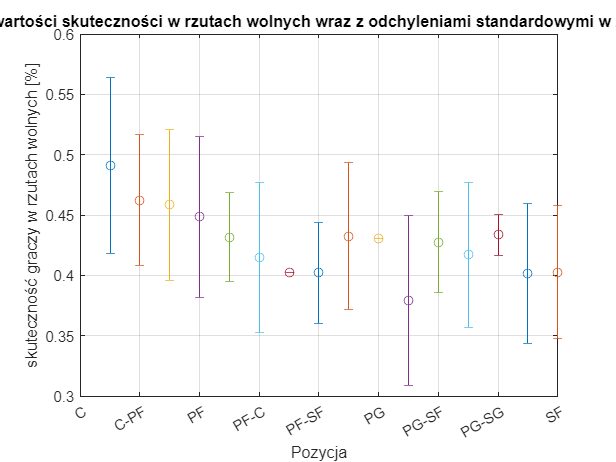

tabela=sortrows(tabela);

skutecznosc_C_tabela=tabela(1:1674,:);
srednia_C=mean(skutecznosc_C_tabela.("dane_skutecznosc"));
skutecznosc_CPF_tabela=tabela(1675:1693,:);
srednia_CPF=mean(skutecznosc_CPF_tabela.("dane_skutecznosc"));
skutecznosc_PF_tabela=tabela(1694:3988,:);
srednia_PF=mean(skutecznosc_PF_tabela.("dane_skutecznosc"));
skutecznosc_PFC_tabela=tabela(3989:4007,:);
srednia_PFC=mean(skutecznosc_PFC_tabela.("dane_skutecznosc"));
skutecznosc_PFSF_tabela=tabela(4008:4028,:);
srednia_PFSF=mean(skutecznosc_PFSF_tabela.("dane_skutecznosc"));
skutecznosc_PG_tabela=tabela(4029:6622,:);
srednia_PG=mean(skutecznosc_PG_tabela.("dane_skutecznosc"));
skutecznosc_PGSF_tabela=tabela(6623:6623,:);
srednia_PGSF=mean(skutecznosc_PGSF_tabela.("dane_skutecznosc"));
skutecznosc_PGSG_tabela=tabela(6624:6652,:);
srednia_PGSG=mean(skutecznosc_PGSG_tabela.("dane_skutecznosc"));
skutecznosc_SF_tabela=tabela(6653:9028,:);
srednia_SF=mean(skutecznosc_SF_tabela.("dane_skutecznosc"));
skutecznosc_SFC_tabela=tabela(9029:9029,:);
srednia_SFC=mean(skutecznosc_SFC_tabela.("dane_skutecznosc"));
skutecznosc_SFPF_tabela=tabela(9030:9051,:);
srednia_SFPF=mean(skutecznosc_SFPF_tabela.("dane_skutecznosc"));
skutecznosc_SFSG_tabela=tabela(9052:9082,:);
srednia_SFSG=mean(skutecznosc_SFSG_tabela.("dane_skutecznosc"));
skutecznosc_SG_tabela=tabela(9083:11762,:);
srednia_SG=mean(skutecznosc_SG_tabela.("dane_skutecznosc"));
skutecznosc_SGPF_tabela=tabela(11763:11766,:);
srednia_SGPF=mean(skutecznosc_SGPF_tabela.("dane_skutecznosc"));
skutecznosc_SGPG_tabela=tabela(11767:11791,:);
srednia_SGPG=mean(skutecznosc_SGPG_tabela.("dane_skutecznosc"));
skutecznosc_SGSF_tabela=tabela(11792:11817,:);
srednia_SGSF=mean(skutecznosc_SGSF_tabela.("dane_skutecznosc"));
nazwy=["C", "C-PF", "PF" ,"PF-C", "PF-SF", "PG", "PG-SF", "PG-SG", "SF", "SF-C", "SF-PF", "SF-SG", "SG", "SG-PF", "SG-PG", "SG-SF"];
srednie=[srednia_C, srednia_CPF, srednia_PF, srednia_PFC, srednia_PFSF, srednia_PG, srednia_PGSF, srednia_PGSG, srednia_SFPF, srednia_SF, srednia_SFC, srednia_SFSG, srednia_SG, srednia_SGPF, srednia_SGPG, srednia_SGSF];
odchylenia=[std(skutecznosc_C_tabela.("dane_skutecznosc")), std(skutecznosc_CPF_tabela.("dane_skutecznosc")), std(skutecznosc_PF_tabela.("dane_skutecznosc")), std(skutecznosc_PFC_tabela.("dane_skutecznosc")), std(skutecznosc_PFSF_tabela.("dane_skutecznosc")), std(skutecznosc_PG_tabela.("dane_skutecznosc")), std(skutecznosc_PGSF_tabela.("dane_skutecznosc")),  std(skutecznosc_PGSG_tabela.("dane_skutecznosc")), std(skutecznosc_SF_tabela.("dane_skutecznosc")), std(skutecznosc_SFC_tabela.("dane_skutecznosc")), std(skutecznosc_SFPF_tabela.("dane_skutecznosc")), std(skutecznosc_SFSG_tabela.("dane_skutecznosc")), std(skutecznosc_SG_tabela.("dane_skutecznosc")),  std(skutecznosc_SGPF_tabela.("dane_skutecznosc")),std(skutecznosc_SGPG_tabela.("dane_skutecznosc")) ,std(skutecznosc_SGSF_tabela.("dane_skutecznosc"))];
figure;
for i=1:16
    errorbar(i,srednie(i),odchylenia(i), odchylenia(i), 'o')
    hold on
end
xticklabels(nazwy)
grid on
title('Wykres średnich wartości skuteczności w rzutach wolnych wraz z odchyleniami standardowymi w zależności od pozycji')
xlabel('Pozycja')
ylabel('skuteczność graczy w rzutach wolnych [%]')